# `matlab-trimesh-stereo-reconstruction`

**Brief:** *Live script for tesellated STL stereo reconstruction of a camera scene's surface via point cloud processing.*

MATLAB computer vision script for stereo reconstruction as a tesselating 3D triangular mesh surface in STL format.

**Dependency tree:**

- [`$matlabroot/toolbox/vision`](https://uk.mathworks.com/products/computer-vision.html)

- [`surf2stl`](https://mathworks.com/matlabcentral/fileexchange/4512)

Install the [`mpm`](https://mathworks.com/matlabcentral/fileexchange/54548-mpm) addon to manage MATLAB script dependencies automatically.

**Files:**

- `script.m` - a command window script

- `app.m` - a GUI script

- `live.mlx` - a live script

## Configuration

**Input:** grayscale stereo images in landscape using the `*.jpg` / `*.jpeg` format (can use any [`imformats`](https://mathworks.com/help/matlab/ref/imformats.html) extension).

- Add checkerboard images from left stereo view to `./config/left`

- Insert checkerboard images from right stereo view to `./config/right`

- Add modelling input images from stereo view to `./input`

**Output:** A 3D representation of the `./input` stereo image set in STL format. Default - `point-cloud.stl` file in script location.

**Requirements**:

- Images should be same orientation as checkerboard to reduce pixel error from reprojection.

- For calibration images, asymmetric (odd-even) checkerboard should be in all views.

- For calibration images, minimum image count per folder is 4 (for low reprojection error).

- For calibration images, naming convention is: `./config/<VIEW>/<VIEW>##.jpg` (e.g. `./config/left/left01.jpg`)

**File tree**:

- `./input`: actual 3D model target scene.

- `./config/left`: left stereo view with checkerboard.

- `./config/right`: right stereo view with checkerboard.

**N.B:** the image file names must be numbered in ascending order.

## Source code

### Setup

#### Environment cleanup

close all;
clear;
clc;

#### Workspace cleanup

filePath = fullfile(pwd, 'data', 'toolbox');
stlPath = 'point-cloud.stl';
if exist(fullfile(filePath, stlPath), 'file')
    recycle on;
    delete(fullfile(filePath, stlPath));
end

#### Load input imageset

inputImages = imageDatastore(fullfile(filePath, 'input'));
I1 = readimage(inputImages, 1);
if size(I1, 3) == 3
    I1 = rgb2gray(I1);
end
I2 = readimage(inputImages, 2);
if size(I2, 3) == 3
    I2 = rgb2gray(I2);
end

#### Dependency management

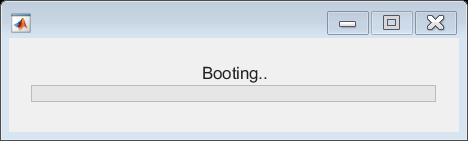

if ~exist("surf2stl", "file")
    if ~matlab.addons.isAddonEnabled("mpm")
        error([                                                         ...
            "Please install MPM as a MATLAB Addon.\n"                   ...
            "<a href="""                                                ...
            "https://mathworks.com/matlabcentral/fileexchange/54548"    ...
            """>"                                                       ...
            "mpm - File Exchange - MATLAB Central"                      ...
            "</a>"                                                      ...

        ])
    else
        mpm install surf2stl;
    end
end

#### User configuration

**Variables:**

- `imageMinimum:` min. no of images in calib folder.

- `approxImageHeight``: `Estimate of furthest scene height in mm.

- `squareWidth``:` Checkerboard square width in mm.

- `ptCloudDensity``: Point density within squareWidth.`

- `sGolayFiltOrder``:` Savitsky-Golay extrapolation curve order.

- `sGolayFiltFrameLen``:` Savitsky-Golay sliding window point count.

- `disparityBMBias:` Algorithm bias to block matching vs semi-global matching (in the range `-1` to `1`).

- `disparityMaxRatio:` Ratio for disparity map ceiling vs maximum disparity (in the range `0` to `1`).

squareWidth = 50;
ptCloudDensity = 5;
sGolayFiltOrder = 3;
sGolayFiltFrameLen = 21;
disparityBMBias = -0.5;
disparityMaxRatio = 0.675;

#### Show loading indicator

Script takes T = ~30s to execute.

wb = waitbar(0, "Booting..");
wb.Visible = "on";

### Camera calibration of stereo images

Code based on MATLAB `rectifyStereoImages` code sample. [[1]](https://www.mathworks.com/help/vision/ref/rectifystereoimages.html)

#### Load stereo calibration imagesets

**Note:** Using a grayscale color space reduces image data & overhead in calibration phase. [[2]](https://www.mathworks.com/help/matlab/ref/rgb2gray.html)

**See:** ["Image inputs"](#image-inputs).

waitbar(0, wb, 'Loading input images.');
calibLeftImages = imageDatastore(fullfile(filePath, 'config', 'left'));
calibRightImages = imageDatastore(fullfile(filePath, 'config', 'right'));

#### Load calibration images

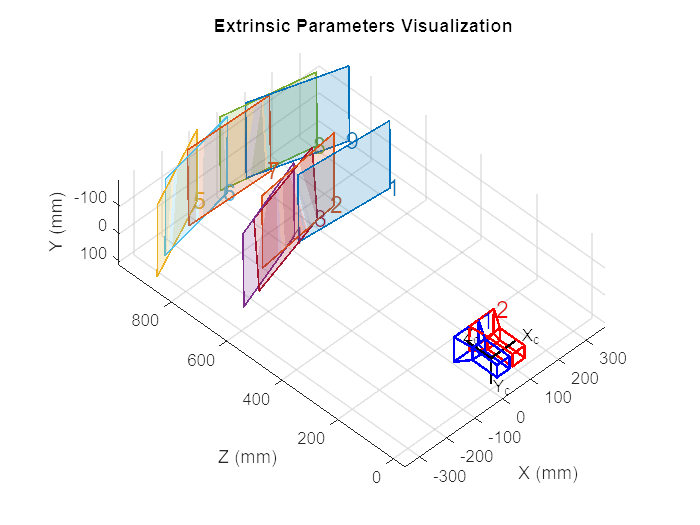

S1 = [size(I1, 1), size(I1, 2)];
S2 = [size(I2, 1), size(I2, 2)];

imageAmounts = struct;
imageAmounts.L = size(calibLeftImages.Files, 1);
imageAmounts.R = size(calibRightImages.Files, 1);

errno{1} = 'stereo2trimesh::ERR_MISMATCH_IMG_COUNT';
errno{2} = 'stereo2trimesh::ERR_CALIB_IMG_INSUFFICIENT';
errno{3} = 'stereo2trimesh::ERR_MISMATCH_IMG_DIM';

if imageAmounts.L ~= imageAmounts.R
    e = [errno{1} ' (L: ' imageAmounts.L ', R: ' imageAmounts.R];
    errordlg(e);
    error(e);
elseif imageAmounts.L < 4
    e = [errno{2} ' (n=' imageAmounts.L ')'];
    errordlg(e);
    error(e);
elseif ~isequal(S1, S2)

    e = [errno{3} ' (L: ' S1(1) 'x' S1(2) 'px, R: ' S2(1) 'x' S2(2) 'px)'];
    errordlg(e);
    error(e);
end

#### Checkerboard detection

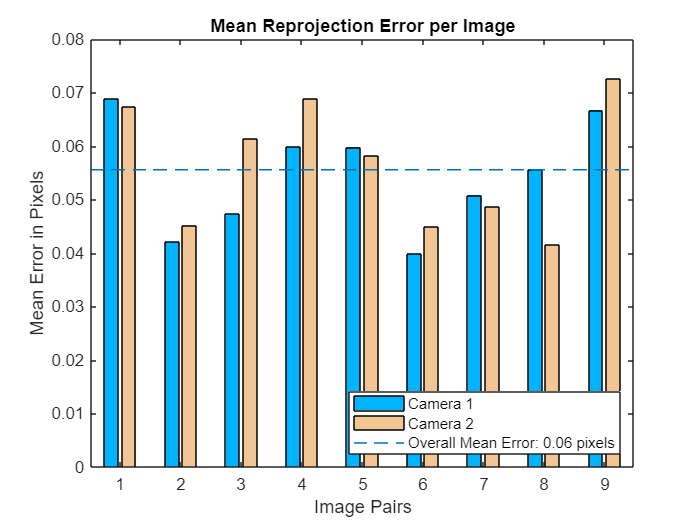

waitbar(0.1, wb, 'Detecting checkerboard keypoints.');

[imagePoints, boardSize] = detectCheckerboardPoints(                    ...


			Standard Errors of Estimated Stereo Camera Parameters
			-----------------------------------------------------

Camera 1 Intrinsics
-------------------
Focal length (pixels):   [ 1036.8087 +/- 0.6771     1036.6726 +/- 0.6630  ]
Principal point (pixels):[  657.0769 +/- 0.3631      485.1551 +/- 0.2743  ]
Skew:                    [    0.1852 +/- 0.0366  ]
Radial distortion:       [   -0.3621 +/- 0.0008        0.1881 +/- 0.0027  ]

Camera 1 Extrinsics
-------------------
Rotation vectors:
                         [   -0.1693 +/- 0.0007        0.0274 +/- 0.0006       -3.1613 +/- 0.0001  ]
                         [    0.2005 +/- 0.0006       -0.0523 +/- 0.0005       -3.0989 +/- 0.0000  ]
                         [    0.4197 +/- 0.0005       -0.1061 +/- 0.0004       -3.1110 +/- 0.0001  ]
                         [    0.5249 +/- 0.0005       -0.0605 +/- 0.0004       -3.0549 +/- 0.0001  ]
                         [    0.6816 +/- 0.0006       -0.0305 +/- 0.0005       -3.0328 +/- 0.0001  ]
 

    calibLeftImages.Files,                                              ...
    calibRightImages.Files                                              ...
);

#### Calculate undistorted checkerboard keypoint coordinates

worldPoints = generateCheckerboardPoints(boardSize, squareWidth);

#### Image validation

**Error:**

- `char` - mismatch in image count between `./config/lef`t & `./config/right.`

- `char` - below 4 images in `./config/left` & `./config/right.`

- `char` - mismatch in resolution of `./input` images.

#### Calibrate stereo camera system

**Parameters:**

- `EstimateSkew`: Are image axes exactly perpendicular? Default: `true.`

- `EstimateTangentialDistortion`: Factor in whether the camera is horizontal. Default: `true`.

- `NumRadialDistortionCoefficients`: Good for fish-eye lenses. Default: `2`.

- `ImageSize`: Matrix for size of image - `imageSize`.

**TODO: **Adjust `estimateCameraParameters` parameters for experimental stage.

waitbar(0.2, wb, "Estimating camera parameters.");
[stereoParams, ~, estimationErrors] = estimateCameraParameters(         ...
    imagePoints,                                                        ...
    worldPoints,                                                        ...
    "EstimateSkew", true,                                               ...
    "EstimateTangentialDistortion", false                               ...
);

#### Display camera extrinisics

**Figure 1** - checkerboard boundary points for calibration experiment.

Reprojection is process of "reprojecting" original image from a camera image.

Most camera images have distortion (e.g. "fisheye" lens effect).

waitbar(0.3, wb, "Showing camera extrinisics.");
figure;
showExtrinsics(stereoParams, "CameraCentric");
view([-45 45]);

#### Graph camera reprojection errors

**Figure 2** - reprojection errors for calibration experiment.

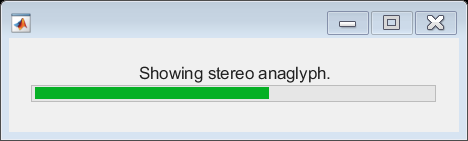

waitbar(0.4, wb, "Showing reprojection errors.");

figure;
showReprojectionErrors(stereoParams);
displayErrors(estimationErrors, stereoParams);

#### Stereo rectification with "valid" output view

The "valid" option is most suitable for computing disparity - it limits the image data to a regular 2D rectangle. [[3]](https://www.mathworks.com/help/vision/ref/rectifystereoimages.html)

**Parameters:**

- `OutputView`: OutputView crops the image to a rectangle, fitting inside the overlapping, curved 3D anaglyph. Default: `valid`.

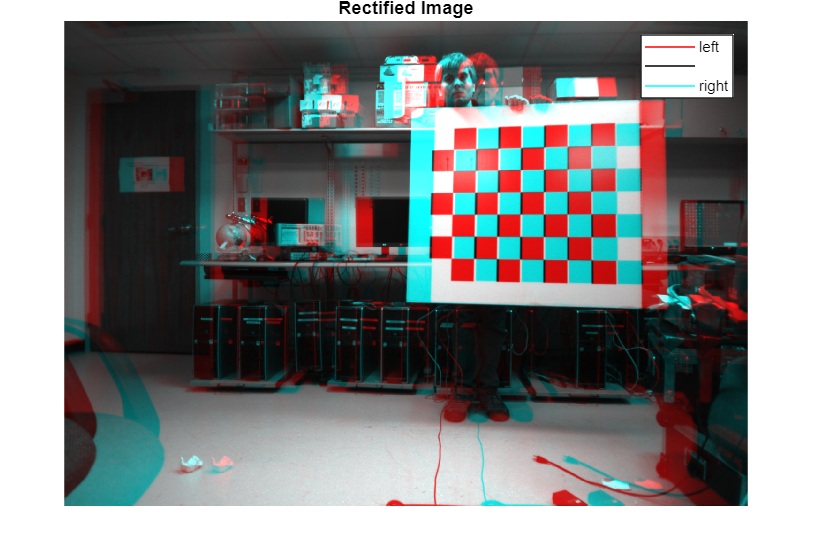

waitbar(0.5, wb, "Showing stereo rectification.");
[F1, F2] = rectifyStereoImages(I1, I2, stereoParams, 'OutputView', 'valid');
pixelDensityMm = mrdivide(                                              ...
    mean([                                                              ...
        stereoParams.CameraParameters1.FocalLength,                     ...
        stereoParams.CameraParameters2.FocalLength                      ...

    ], 2),                                                              ...
    mean([                                                              ...
        stereoParams.CameraParameters1.IntrinsicMatrix(1, 1),           ...
        stereoParams.CameraParameters2.IntrinsicMatrix(1, 1)            ...
    ], 2)                                                               ...
);
approxImageHeight = 2 * mean([size(F1, 1), size(F2, 1)], 2) / pixelDensityMm;
approxImageWidth = 2 * mean([size(F1, 2), size(F2, 2)], 2) / pixelDensityMm;

#### Display an "valid" output anaglyph image

**Figure 3** - stereo anaglyph.

waitbar(0.6, wb, "Showing stereo anaglyph.");
figure;
hold on;
labels{1} = plot(nan, nan, 'color', 'red');
labels{2} = plot(nan, nan, 'color', 'black');
labels{3} = plot(nan, nan, 'color', 'cyan');
legend([labels{:}], {'left', '', 'right'});
imshow(stereoAnaglyph(F1, F2));
axis tight;
title 'Rectified Image';

### Disparity computation from stereo images

Code based on MATLAB `disparitySGM` code sample.[[4]](https://www.mathworks.com/help/vision/ref/disparitysgm.html)

#### Compute disparity map from stereo images

Generate a disparity (Cartesian *z*-depth) colormap of the scene. We take a biased average of the disparity map produced by semi-global and block matching algorithms. This ensures reduced "hole" (neutral) amplitudes in the disparity data.

**TODO:**

- Adjust `disparityBMBias` as appropriate for the image input.

- Adjust the range maximum to $c\times2^4,c\in\mathbb{N}$ to remove outliers or camera noise.

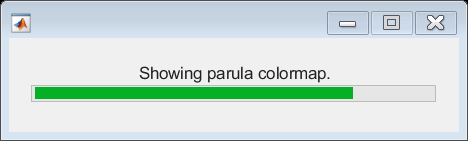

waitbar(0.7, wb, "Computing disparity map.");
disparityMapBM = disparityBM(F1, F2, "DisparityRange", [0, 64]);
disparityMapSGM = disparitySGM(F1, F2, "DisparityRange", [0, 64]);

disparityMapBM(isnan(disparityMapBM)) = 0;
disparityMapSGM(isnan(disparityMapSGM)) = 0;

disparityBMQuotient = (1 + disparityBMBias) / 2;

disparitySGMQuotient = (1 - disparityBMBias) / 2;

disparityMap = disparityBMQuotient * disparityMapBM + disparitySGMQuotient * disparityMapSGM;
disparityMap(disparityMap==0) = NaN;

#### Remove unwanted transients

Limit disparity values to ~90% of the maximum to remove maximal transients.

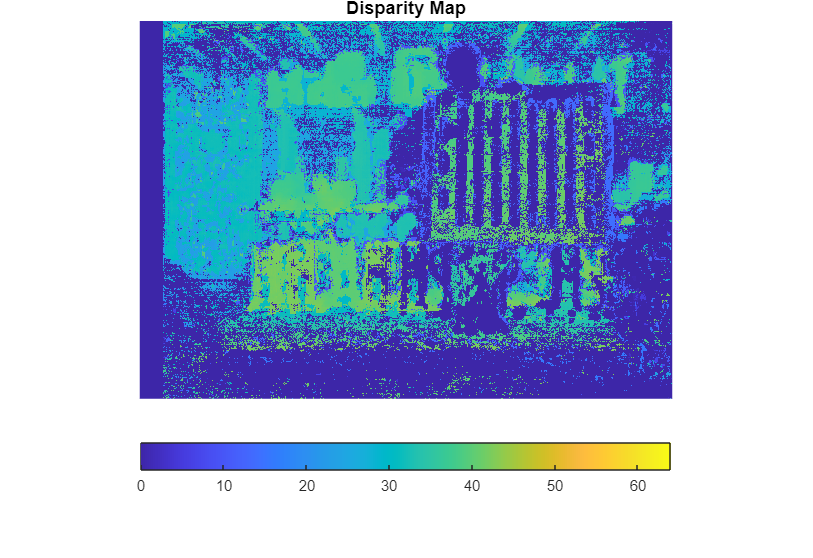

disparityMapCeil = disparityMaxRatio * max(max(disparityMap));
disparityMap(disparityMap>=disparityMapCeil) = NaN;

#### Display disparity map

**Figure 4** - disparity map as `parula` colormap image.

waitbar(0.8, wb, "Showing parula colormap.");
figure;
imshow(disparityMap, [0, 64]);
title 'Disparity Map';
axis tight;
colormap parula;
colorbar southoutside;

### Point cloud generation

#### Reconstruct organised point cache matrix

Converts the disparity map into a point cloud. Produces raw geometric dataset in *m* - standard STL dimensions.

waitbar(0.9, wb, "Generating point cloud.");
rawPoints3D = reconstructScene(disparityMap, stereoParams);
rawPoints3D(isinf(rawPoints3D)) = NaN;
rawPoints3D = double(rawPoints3D) ./ 1000;

#### Initialise axial, co-ordinate point cloud cache

pointsCache = struct;
axesKeys = ["X", "Y", "Z"];
for m = 1:3
    k = char(axesKeys(m));
    p = rawPoints3D(:, :, m);
    pointsCache.(k) = p;
end
clearvars p k;

#### Compute checkerboard centroid as struct

Compute checkerboard position as a Cartesian coordinate in the point cloud. It's the mean of the co-ordinate set closest to the origin in the *z*-axis.

**TODO:** See if I need to change `min` in some way (assumes convex).

checkerboardCentroid = struct;
checkerboardCentroid.Z = min(min(pointsCache.Z));
checkerboardIndex = sort(find(checkerboardCentroid.Z == pointsCache.Z));
checkerboardCentroid.X = 0;
checkerboardCentroid.Y = 0;

#### Restrict point cloud to image scene dimensions

Limits:

- point cloud width *x* = √2 × scene image width

- point cloud height *y* = √2 × scene image height

- point cloud length *z* = √0.5 × (scene image height + scene image width)

waitbar(0.9, wb, "Filter-processing point cloud co-ordinates.");
limits = struct;
cacheAxes = char(fieldnames(pointsCache));

for m = 1:3
    switch m
        case 1
            bound = sqrt(2) / 2 * approxImageWidth;
        case 2
            bound = sqrt(2) / 2 * approxImageHeight;
        otherwise
            bound = mean([approxImageHeight, approxImageWidth], 2) / 2;
    end

    k = cacheAxes(m);
    c = checkerboardCentroid.(k);
    l = bound/1000;

    lim = [c - l, c + l];
    limits.(k) = lim;

    p = pointsCache.(k);
    p(p < lim(1) | p > lim(2)) = NaN;
    pointsCache.(k) = p;
end

clearvars k lim p;

#### Filter point cloud for invalid values

Remove invalid `NaN` values inside point cloud.

- Raw values that are `+Inf `/ `-Inf` / `NaN`.

- Points that fall outside range of point cloud.

nanPoints = ( 0                                                         ...
    | isnan(pointsCache.X)                                              ...
    | isnan(pointsCache.Y)                                              ...
    | isnan(pointsCache.Z)                                              ...
);

for m = 1:3
    k = cacheAxes(m);
    p = pointsCache.(k);
    p(nanPoints) = checkerboardCentroid.(k);
    pointsCache.(k) = p;
end

clearvars k p;

### Surface mesh conversion

#### Surface mesh denoising and interpolation

Generate a organised point cloud as a struct with 1 axis per field. Code adapted from StackOverflow. [[5]](https://stackoverflow.com/a/39576639)

**See: **[https://commons.wikimedia.org/wiki/File:Lissage_sg3_anim.gif](https://commons.wikimedia.org/wiki/File:Lissage_sg3_anim.gif)

- The `scatteredInterpolant` factory function computes interpolant. [[6]](https://www.mathworks.com/help/matlab/ref/scatteredinterpolant.html)

- MATLAB maps `meshgrid` regular matrix of *x*-*y* points.

- Savitzky-Golay filter used to denoise points in Z axis.

waitbar(0.9, wb, "Interpolating point cloud as surface mesh.");
gs = (1 / ptCloudDensity) * (squareWidth / 1000);

I = scatteredInterpolant(pointsCache.X(:), pointsCache.Y(:), pointsCache.Z(:), "natural");

gridPoints = struct;
intX = min(pointsCache.X(:)):gs:max(pointsCache.X(:));
intY = min(pointsCache.Y(:)):gs:max(pointsCache.Y(:));
[gridPoints.X, gridPoints.Y] = meshgrid(intX, intY);

gridPoints.Z = I(gridPoints.X, gridPoints.Y);
intZ1 = sgolayfilt(gridPoints.Z.', sGolayFiltOrder, sGolayFiltFrameLen);
intZ2 = sgolayfilt(gridPoints.Z, sGolayFiltOrder, sGolayFiltFrameLen);
gridPoints.Z = (intZ1.' + intZ2)/2;

#### **Restore correct Cartesian axes in coordinate system**

Apply geometric transforms to gridded point clouds:

- $-1$ scalar transformation of *y*-axis (vertical axis of the planar image)

- $-1$ scalar transformation of *z*-axis (depth axis of the planar image scene)

gridPoints = struct('X', gridPoints.X, 'Y', -1 .* gridPoints.Y, 'Z', -1 .* gridPoints.Z);

#### Create 3-by-3 point cloud scatter matrix

points3D = double.empty();
for m = 1:3
    points3D(:, :, m) = gridPoints.(cacheAxes(m));
end

clearvars cacheAxes;

#### Mesh triangulation view of point cloud

**Figure 5** - 3D connected surface plot of the point cloud.

**Note:** We reverse the geometric transforms.

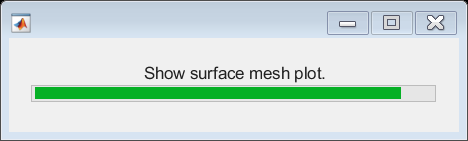

waitbar(0.925, wb, "Show surface mesh plot.");

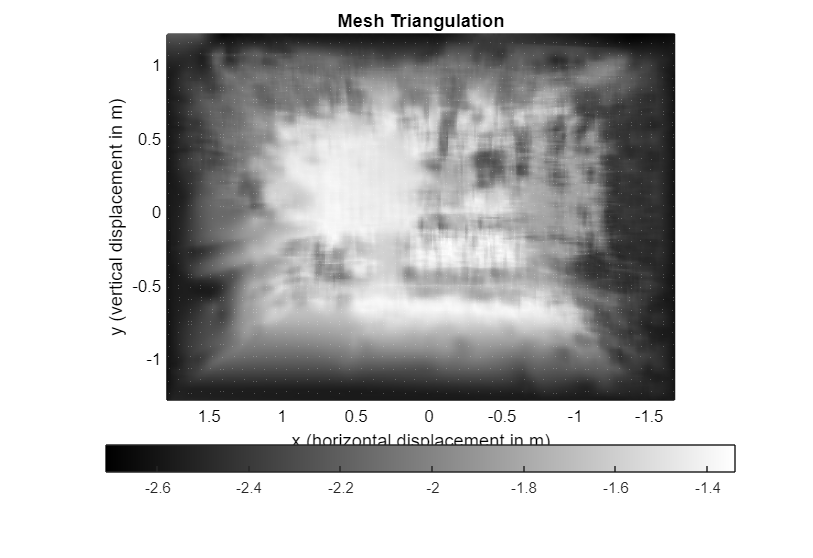

mesh(gridPoints.X, gridPoints.Y, gridPoints.Z);
title 'Mesh Triangulation';
xlabel 'x (horizontal displacement in m)';
ylabel 'y (vertical displacement in m)';
zlabel 'z (scene depth in m)';

set(gcf, "Color", "w");
set(gca, "XColor", "k");
set(gca, "YColor", "k");
set(gca, "ZColor", "k");
set(gca, "LineWidth", 0.1);

axis equal;
view([180 -90]);

colormap gray;
colorbar southoutside;
rotate3d on;

### STL file generation from point cloud

Using `surf2stl` for high stability & speed (low interpolation).

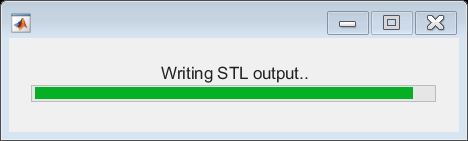

waitbar(0.95, wb, "Writing STL output..");

stlPath = char(fullfile(pwd, stlPath));
surf2stl(stlPath, gridPoints.X, gridPoints.Y, gridPoints.Z);

Wrote 172308 facets


### Teardown

waitbar(1, wb, "Done!");
winopen(stlPath);
close(wb);

### References

- [https://www.mathworks.com/help/matlab/ref/rgb2gray.html](https://www.mathworks.com/help/matlab/ref/rgb2gray.html)

- [https://www.mathworks.com/help/vision/examples/depth-estimation-from-stereo-video.html](https://www.mathworks.com/help/vision/examples/depth-estimation-from-stereo-video.html)

- [https://www.mathworks.com/help/vision/ref/rectifystereoimages.html](https://www.mathworks.com/help/vision/ref/rectifystereoimages.html)

- [https://www.mathworks.com/help/vision/ref/disparitysgm.html](https://www.mathworks.com/help/vision/ref/disparitysgm.html)

- [https://www.mathworks.com/help/matlab/ref/scatteredinterpolant.html](https://www.mathworks.com/help/matlab/ref/scatteredinterpolant.html)

- [https://stackoverflow.com/a/39576639](https://stackoverflow.com/a/39576639)